# Statistics on physiological data from VR

Sam Michalka

May 19, 2023

## Set up

conditions = categorical({'x3Combination','x4Combination','x5Combination','x6Combination'});
conditionValues = 3:6;

## Performance

### Load data

raw_performance_data = readtable("performance.xlsx","VariableNamingRule",'modify');

raw_performance_data.Properties.VariableNames{1} = 'ID'; % Rename 
raw_performance_data(raw_performance_data.ID == "",:) = [];
raw_performance_data.ID = categorical(raw_performance_data.ID)

raw_performance_data = 19×5 table
    ID     x3Combination    x4Combination    x5Combination    x6Combination
    ___    _____________    _____________    _____________    _____________

    A02       0.93333           0.9625             0.91          0.81579   
    A05       0.98148          0.89706             0.85          0.91667   
    A07       0.96491          0.90789          0.97895            0.875   
    A08       0.94737          0.96053                1          0.92982   
    A09             1          0.93421             0.84          0.74167   
    A10          0.95          0.90789          0.76842          0.79167   
    A11       0.98246                1             0.98          0.92982   
    A12       0.96667                1             0.94          0.60833   
    A13       0.98246           0.8

fprintf("Total number of subjects is: %d",height(raw_performance_data))

Total number of subjects is: 19

### Normality

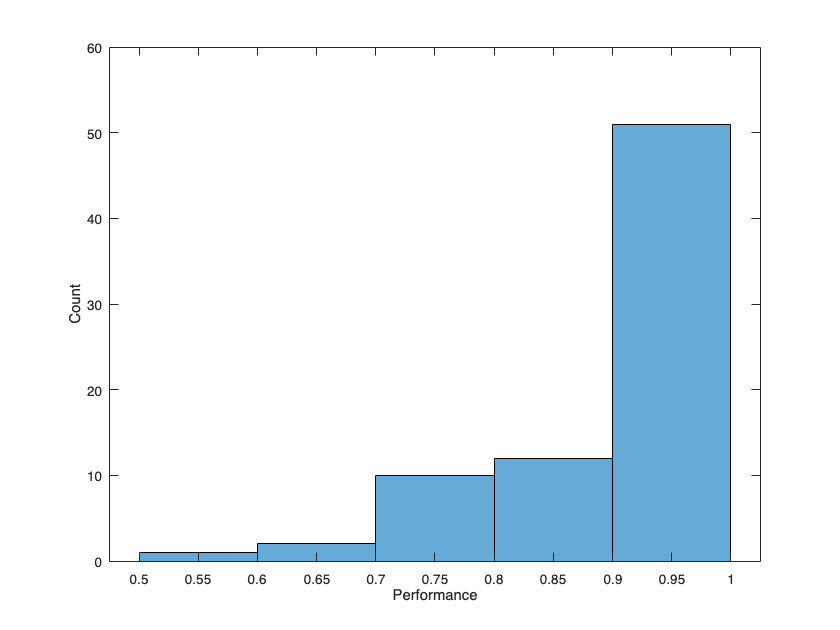

figure; histogram(raw_performance_data{:,2:end}); xlabel("Performance");ylabel("Count");

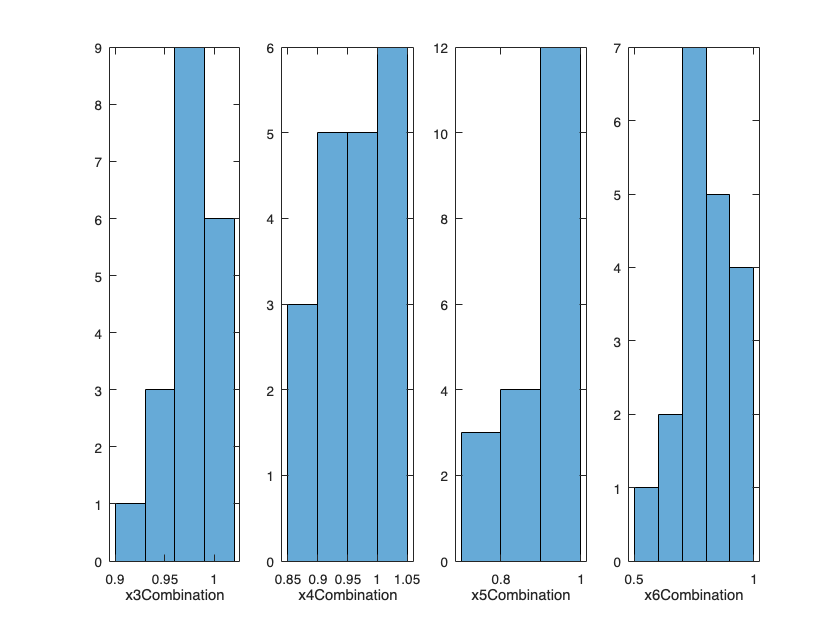

% store the data in a temporary variable to make code easy to copy, assumes
% rows are subjects and the columns are the values for 3-6 respectively
tempData3to6 = raw_performance_data{:,2:end};
figure;
for i = 1:size(tempData3to6,2)
    subplot(1,size(tempData3to6,2),i);
    histogram(tempData3to6(:,i));
    xlabel(string(conditions(i)));
end

### All subject plot

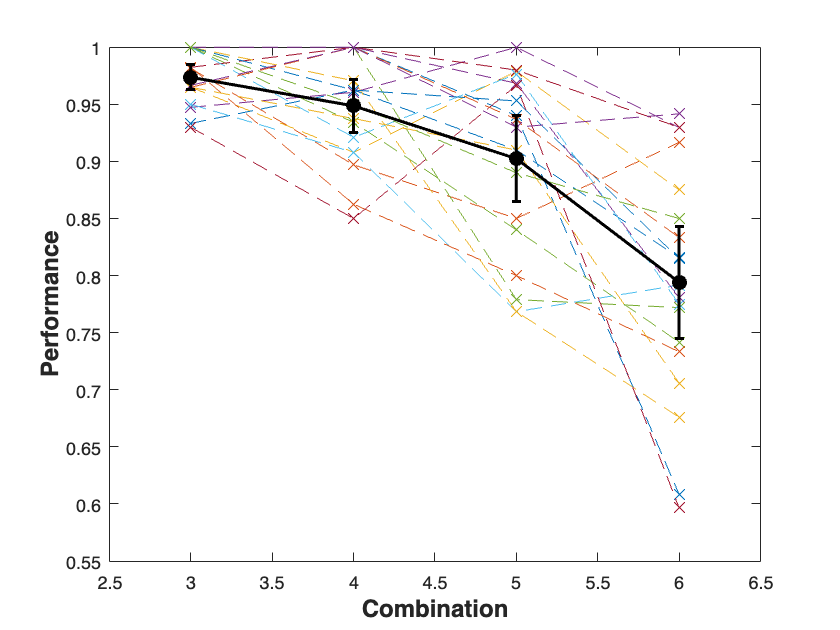

figure;

for i = 1:size(tempData3to6,1)
    plot(conditionValues,tempData3to6(i,:),'x--','MarkerSize',10);
    hold on;  
end
errorVals = calculateError(tempData3to6,'95sem');
errorbar(conditionValues,mean(tempData3to6),errorVals,'k','LineWidth',2);
hold on;
plot(conditionValues,mean(tempData3to6),'k.','MarkerSize',30);
fontsize(gca,12,'points')
xlim([2.5 6.5]); xlabel('Combination','FontSize',16,"FontWeight","bold");
ylabel('Performance','FontSize',16,"FontWeight","bold");

### Repeated Measures ANOVA

We are violating the assumption for normality for the performance data, which is heavily skewed. 

withinDesign = table([1 2 3 4]','VariableNames',{'Load'});
withinDesign.Load = categorical(withinDesign.Load);
rm_performance = fitrm(raw_performance_data,'x3Combination-x6Combination ~ 1','WithinDesign',withinDesign);
rm_performance_anova = ranova(rm_performance,'WithinModel','Load')

rm_performance_anova = 4×8 table
                         SumSq     DF     MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                        _______    __    _________    ______    __________    __________    __________    __________

    (Intercept)          62.206     1       62.206    9102.5    8.4323e-26    8.4323e-26    8.4323e-26    8.4323e-26
    Error               0.12301    18     0.006834                                                                  
    (Intercept):Load    0.35962     3      0.11987    28.642    3.2245e-11    5.7088e-09    5.1828e-10    4.3637e-05
    Error(Load)           0.226    54    

Regardless of p-value (you should check which is the correct one to report for this non-normal data), we see a strong effect of Load here. This is also obvious from the plots. 

rm_performance_mult = multcompare(rm_performance,'Load')

rm_performance_mult = 12×7 table
    Load_1    Load_2    Difference     StdErr       pValue        Lower         Upper  
    ______    ______    __________    ________    __________    __________    _________

      1         2        0.025036     0.011226       0.15283    -0.0066936     0.056765
      1         3        0.071254     0.019308     0.0082787      0.016685      0.12582
      1         4         0.17958     0.023733    2.9923e-06       0.11251      0.24666
      2         1       -0.025036     0.011226       0.15283     -0.056765    0.0066936
      2         3        0.046218     0.019344       0.11513    -0.0084544      0.10089
      2         4         0.15455     0.023251     1.698e-05      0.088831      0.22026
      3         1       

### Compare categorical and linear models

We can check to see if the data is better fit by a model that treats load as categorical or a model that treats it as continuous data.

First, we must reshape the data so it is organized as expected for the model.

long_performance_data = stack(raw_performance_data,string(conditions),"IndexVariableName","Load","NewDataVariableName",'Values');
temp_load = char(long_performance_data.Load);
%temp_load = temp_load(:,2);
long_performance_data.LoadVal = str2num(temp_load(:,2));%#ok

Then we build a set of models to compare.

lme_performance_cat = fitlme(long_performance_data,'Values ~ 1 + Load + (1|ID)', FitMethod='ML'); % Load as a categorical variable
lme_performance_cont = fitlme(long_performance_data,'Values ~ 1 + LoadVal + (1|ID)', FitMethod='ML'); %Load as a continuous variable
lme_performance_cont_err = fitlme(long_performance_data,'Values ~ 1 + LoadVal + (1 + LoadVal|ID)', FitMethod='ML'); %Load as a continuous variable and independent slopes
lme_performance_cat_err = fitlme(long_performance_data,'Values ~ 1 + Load + (1 + Load|ID)', FitMethod='ML'); % Load as a categorical variable

We compare the models to see which is best.

compare(lme_performance_cont,lme_performance_cont_err)

ans =     Theoretical Likelihood Ratio Test

    Model                       DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue  
    lme_performance_cont        4      -179.2    -169.87    93.598                                 
    lme_performance_cont_err    6     -185.85    -171.86    98.923    10.65     2          0.004868


compare(lme_performance_cont,lme_performance_cat)

ans =     Theoretical Likelihood Ratio Test

    Model                   DF    AIC       BIC        LogLik    LRStat    deltaDF    pValue  
    lme_performance_cont    4     -179.2    -169.87    93.598                                 
    lme_performance_cat     6     -183.3    -169.32    97.652    8.1075    2          0.017357


compare(lme_performance_cat,lme_performance_cat_err)

ans =     Theoretical Likelihood Ratio Test

    Model                      DF    AIC       BIC        LogLik    LRStat    deltaDF    pValue    
    lme_performance_cat         6    -183.3    -169.32    97.652                                   
    lme_performance_cat_err    15    -204.7    -169.73    117.35    39.391    9          9.7912e-06


anova(lme_performance_cat)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        3922.4    1      72     1.5389e-64
    {'Load'       }        30.233    3      72      9.267e-13


anova(lme_performance_cat_err)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat    DF1    DF2    pValue    
    {'(Intercept)'}        35720    1      72     7.9424e-99
    {'Load'       }        20.99    3      72      7.107e-10


The best model is using the load as categorical, so we can just us repeated measures ANOVA here.

lme_performance_cat_err

lme_performance_cat_err = Linear mixed-effects model fit by ML

Model information:
    Number of observations              76
    Fixed effects coefficients           4
    Random effects coefficients         76
    Covariance parameters               11

Formula:
    Values ~ 1 + Load + (1 + Load | ID)

Model fit statistics:
    AIC       BIC        LogLikelihood    Deviance
    -204.7    -169.73    117.35           -234.7  

Fixed effects coefficients (95% CIs):
    Name                          Estimate     SE           tStat      DF    pValue        Lower        Upper    
    {'(Intercept)'       }          0.97368    0.0051518        189    72    7.9424e-99      0.96341      0.98395
    {'Load_x4Combination'}        -0.025036     0.010927    -2.2912    72      0.024883    -0.046818    -0.003253
    {'Load_x5Combination'}        -0.071254     0.018793    -3.7916    72    0.00030856     -0.10872    

anova(lme_performance_cat_err)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat    DF1    DF2    pValue    
    {'(Intercept)'}        35720    1      72     7.9424e-99
    {'Load'       }        20.99    3      72      7.107e-10



lme_performance_cat_reml = fitlme(long_performance_data,'Values ~ 1 + Load + (1|ID)', FitMethod='REML') % Load as a categorical variable

lme_performance_cat_reml = Linear mixed-effects model fit by REML

Model information:
    Number of observations              76
    Fixed effects coefficients           4
    Random effects coefficients         19
    Covariance parameters                2

Formula:
    Values ~ 1 + Load + (1 | ID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -157.35    -143.69    84.677           -169.35 

Fixed effects coefficients (95% CIs):
    Name                          Estimate     SE          tStat      DF    pValue        Lower        Upper    
    {'(Intercept)'       }          0.97368    0.015973     60.959    72    1.0402e-63      0.94184       1.0055
    {'Load_x4Combination'}        -0.025036    0.020989    -1.1928    72       0.23687    -0.066877     0.016806
    {'Load_x5Combination'}        -0.071254    0.020989    -3.3948    72     0.0011205      -0.1131    -0.029

% This method most closely matches the rm anova. The df are different, as
% is the F-value for the intercept.
%anova(lme_performance_cat_reml)

## Heart Rate

### Load data

raw_HR_data = readtable("HR.xlsx",'VariableNamingRule','modify');

raw_HR_data.Properties.VariableNames{1} = 'ID'; % Rename 
% Remove rows with no subject name (these were blank and an average)
raw_HR_data(raw_HR_data.ID == "",:) = [];
raw_HR_data.ID = categorical(raw_HR_data.ID)

raw_HR_data = 11×5 table
    ID     x3Combination    x4Combination    x5Combination    x6Combination
    ___    _____________    _____________    _____________    _____________

    A02       -2.4945          0.14817            3.5628          2.8037   
    A07       -3.5676          -3.7134           -4.2075         -3.1171   
    A09        4.1103          0.19397            4.8295           1.322   
    A10       0.77023           4.7444            2.8956          4.0366   
    A11        5.2226           2.8707           -1.3512          -1.499   
    A12       0.53313           2.4832            2.9157          1.0076   
    A13        3.7576          -1.2642           -5.4753         -2.2641   
    A14       -7.7945          -1.9062           -4.8391         -3.1002   
    A19        3.4824          0.86134      

fprintf("Total number of subjects is: %d",height(raw_HR_data))

Total number of subjects is: 11

### Plot data

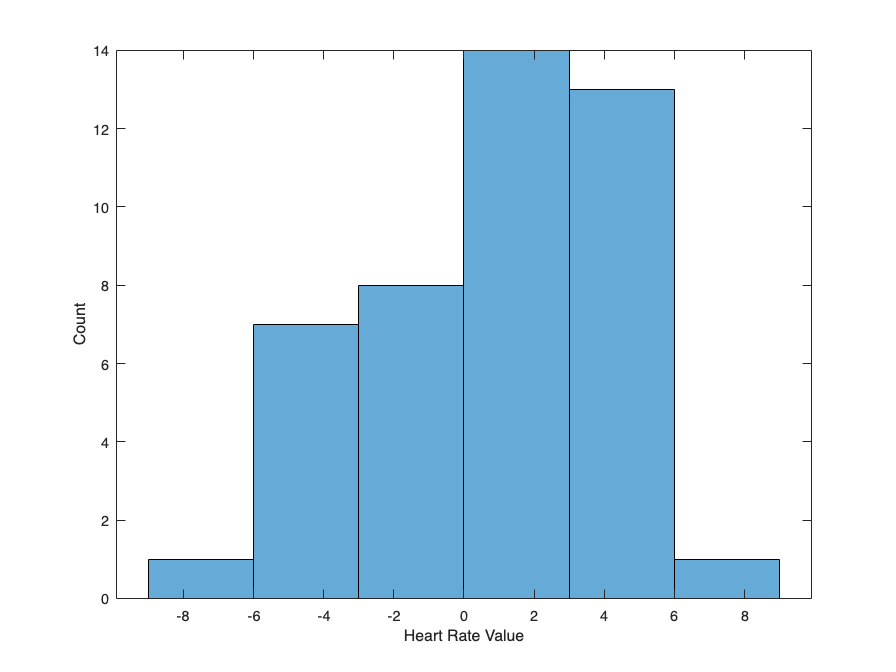

tempData3to6 = raw_HR_data{:,2:end};
metricLabel = "Heart Rate Value";

figure; histogram(tempData3to6); xlabel(metricLabel);ylabel("Count");

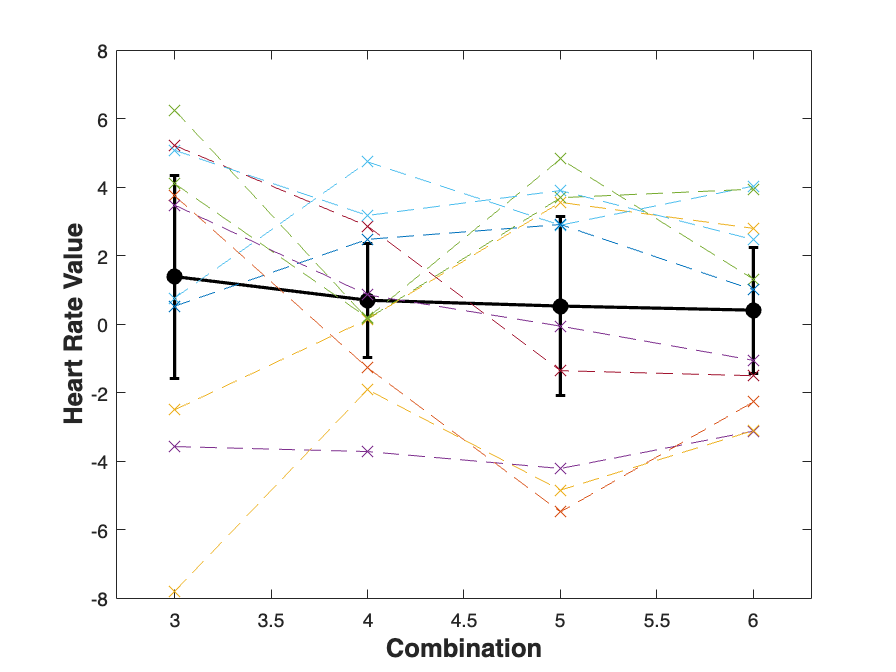

% store the data in a temporary variable to make code easy to copy, assumes
% rows are subjects and the columns are the values for 3-6 respectively

figure;
errorVals = calculateError(tempData3to6,'95sem');
errorbar(conditionValues,mean(tempData3to6),errorVals,'k','LineWidth',2);
hold on;
plot(conditionValues,mean(tempData3to6),'k.','MarkerSize',30);
for i = 1:size(tempData3to6,1)
    plot(conditionValues,tempData3to6(i,:),'x--','MarkerSize',10);
    hold on;  
end
fontsize(gca,12,'points')
xlim([2.7 6.3]); xlabel('Combination','FontSize',16,"FontWeight","bold");
ylabel(metricLabel,'FontSize',16,"FontWeight","bold");

### Repeated Measures ANOVA

withinDesign = table([1 2 3 4]','VariableNames',{'Load'});
withinDesign.Load = categorical(withinDesign.Load);
rm_HR = fitrm(raw_HR_data,'x3Combination-x6Combination ~ 1','WithinDesign',withinDesign);
rm_HR_anova = ranova(rm_HR,'WithinModel','Load')

rm_HR_anova = 4×8 table
                        SumSq     DF    MeanSq       F       pValue     pValueGG    pValueHF    pValueLB
                        ______    __    ______    _______    _______    ________    ________    ________

    (Intercept)         25.617     1    25.617    0.83406    0.38259    0.38259     0.38259     0.38259 
    Error               307.14    10    30.714                                                          
    (Intercept):Load    6.3519     3    2.1173    0.36297    0.78018    0.68853     0.72937     0.56028 
    Error(Load)            175    30    5.8334                                                          


### Compare categorical and linear models

We can check to see if the data is better fit by a model that treats load as categorical or a model that treats it as continuous data.

First, we must reshape the data so it is organized as expected for the model.

long_HR_data = stack(raw_HR_data,string(conditions),"IndexVariableName","Load","NewDataVariableName",'Values');
temp_load = char(long_HR_data.Load);
%temp_load = temp_load(:,2);
long_HR_data.LoadVal = str2num(temp_load(:,2));%#ok

Then we build a set of models to compare.

lme_HR_cat = fitlme(long_HR_data,'Values ~ 1 + Load + (1|ID)', FitMethod='ML'); % Load as a categorical variable
lme_HR_cont = fitlme(long_HR_data,'Values ~ 1 + LoadVal + (1|ID)', FitMethod='ML'); %Load as a continuous variable
lme_HR_cont_err = fitlme(long_HR_data,'Values ~ 1 + LoadVal + (1 + LoadVal|ID)', FitMethod='ML'); %Load as a continuous variable and independent slopes
lme_HR_cat_err = fitlme(long_HR_data,'Values ~ 1 + Load + (1 + Load|ID)', FitMethod='ML'); % Load as a categorical variable

We compare the models to see which is best.

compare(lme_HR_cont,lme_HR_cont_err)

ans =     Theoretical Likelihood Ratio Test

    Model              DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lme_HR_cont        4     224.73    231.87    -108.37                                
    lme_HR_cont_err    6     226.24    236.94    -107.12    2.4976    2          0.28685


compare(lme_HR_cont,lme_HR_cat)

ans =     Theoretical Likelihood Ratio Test

    Model          DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lme_HR_cont    4     224.73    231.87    -108.37                                 
    lme_HR_cat     6     228.54    239.25    -108.27    0.19143    2          0.90872


compare(lme_HR_cat,lme_HR_cat_err)

ans =     Theoretical Likelihood Ratio Test

    Model             DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue  
    lme_HR_cat         6    228.54    239.25    -108.27                                 
    lme_HR_cat_err    15    228.05    254.81    -99.024    18.495    9          0.029844


The continuous model for HR has the lowest AIC and BIC. It is summarized below.

lme_HR_cont

lme_HR_cont = Linear mixed-effects model fit by ML

Model information:
    Number of observations              44
    Fixed effects coefficients           2
    Random effects coefficients         11
    Covariance parameters                2

Formula:
    Values ~ 1 + LoadVal + (1 | ID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    224.73    231.87    -108.37          216.73  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat       DF    pValue     Lower       Upper  
    {'(Intercept)'}          2.1644      1.612      1.3427    42    0.18658     -1.0887     5.4175
    {'LoadVal'    }        -0.31141    0.31142    -0.99999    42    0.32304    -0.93988    0.31705

Random effects covariance parameters (95% CIs):
Group: ID (11 Levels)
    Name1                  Name2                  Type           Estimate    Lo

anova(lme_HR_cont)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat      DF1    DF2    pValue 
    {'(Intercept)'}         1.8028    1      42     0.18658
    {'LoadVal'    }        0.99998    1      42     0.32304


lme_HR_cont.Rsquared

ans = struct with fields:
    Ordinary: 0.5243
    Adjusted: 0.5129


## GSR

### Load data

raw_GSR_data = readtable("GSR.xlsx",'VariableNamingRule','modify');

raw_GSR_data.Properties.VariableNames{1} = 'ID'; % Rename 
% Remove rows with no subject name (these were blank and an average)
raw_GSR_data(raw_GSR_data.ID == "",:) = [];
raw_GSR_data.ID = categorical(raw_GSR_data.ID)

raw_GSR_data = 17×5 table
    ID     x3Combination    x4Combination    x5Combination    x6Combination
    ___    _____________    _____________    _____________    _____________

    A07       0.010995        0.0040392         0.011231         0.015193  
    A02      -0.049404        -0.061226        -0.079612         0.097689  
    A05        0.05144         0.094529          0.10143       -0.0095893  
    A08       0.049648        -0.057517        -0.023146        -0.030024  
    A09     -0.0087993         0.025374         0.091656          0.26537  
    A10      -0.037008        -0.017858         0.017592         0.038762  
    A11      -0.073656       0.00024861         0.047926          0.17163  
    A12       0.011378         0.014184         0.036386         0.024821  
    A13       0.019398       -0.0016524    

fprintf("Total number of subjects is: %d",height(raw_GSR_data))

Total number of subjects is: 17

### Plot data

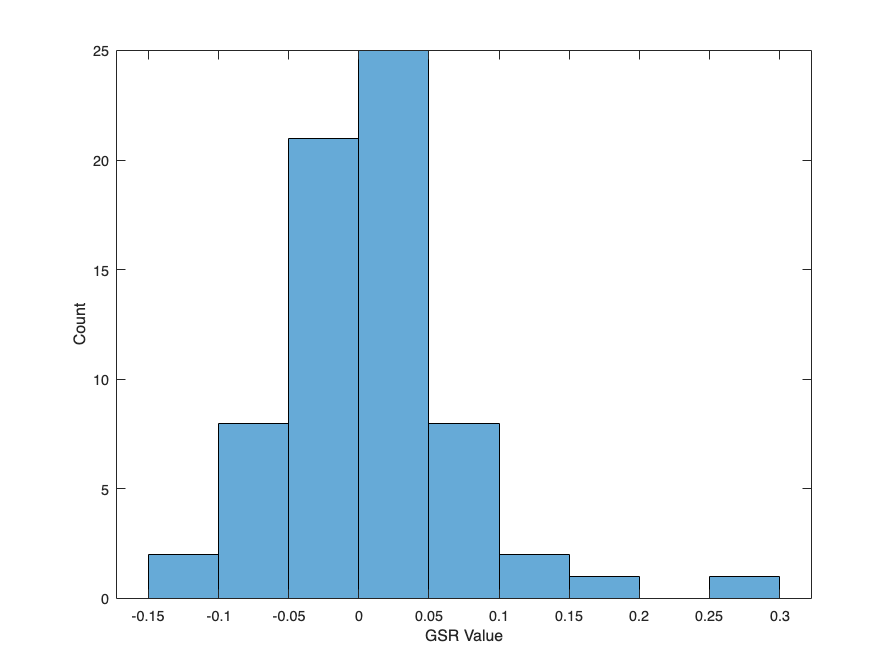

tempData3to6 = raw_GSR_data{:,2:end};
metricLabel = "GSR Value";

figure; histogram(tempData3to6); xlabel(metricLabel);ylabel("Count");

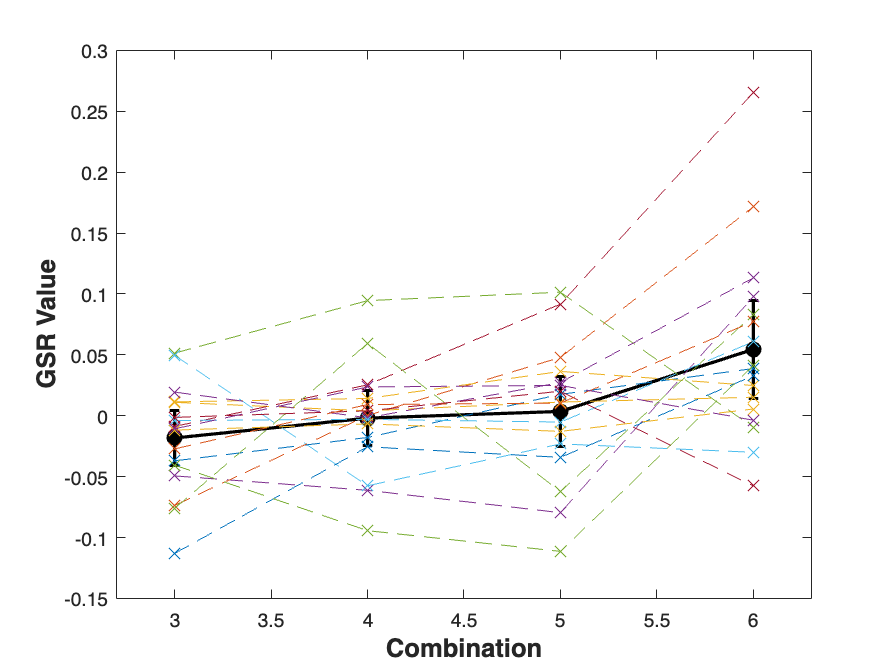

% store the data in a temporary variable to make code easy to copy, assumes
% rows are subjects and the columns are the values for 3-6 respectively

figure;
errorVals = calculateError(tempData3to6,'95sem');
errorbar(conditionValues,mean(tempData3to6),errorVals,'k','LineWidth',2);
hold on;
plot(conditionValues,mean(tempData3to6),'k.','MarkerSize',30);
for i = 1:size(tempData3to6,1)
    plot(conditionValues,tempData3to6(i,:),'x--','MarkerSize',10);
    hold on;  
end
fontsize(gca,12,'points')
xlim([2.7 6.3]); xlabel('Combination','FontSize',16,"FontWeight","bold");
ylabel(metricLabel,'FontSize',16,"FontWeight","bold");

### Repeated Measures ANOVA

withinDesign = table([1 2 3 4]','VariableNames',{'Load'});
withinDesign.Load = categorical(withinDesign.Load);
rm_GSR = fitrm(raw_GSR_data,'x3Combination-x6Combination ~ 1','WithinDesign',withinDesign);
rm_GSR_anova = ranova(rm_GSR,'WithinModel','Load')

rm_GSR_anova = 4×8 table
                          SumSq      DF     MeanSq        F        pValue      pValueGG     pValueHF     pValueLB
                        _________    __    _________    ______    _________    _________    _________    ________

    (Intercept)         0.0060754     1    0.0060754    1.2475      0.28052      0.28052      0.28052     0.28052
    Error                0.077918    16    0.0048699                                                             
    (Intercept):Load     0.050384     3     0.016795     6.186    0.0012186    0.0073855    0.0053968    0.024293
    Error(Load)           0.13032    48     0.002715            

### Compare categorical and linear models

We can check to see if the data is better fit by a model that treats load as categorical or a model that treats it as continuous data.

First, we must reshape the data so it is organized as expected for the model.

long_GSR_data = stack(raw_GSR_data,string(conditions),"IndexVariableName","Load","NewDataVariableName",'Values');
temp_load = char(long_GSR_data.Load);
%temp_load = temp_load(:,2);
long_GSR_data.LoadVal = str2num(temp_load(:,2));%#ok

Then we build a set of models to compare.

lme_GSR_cat = fitlme(long_GSR_data,'Values ~ 1 + Load + (1|ID)', FitMethod='ML'); % Load as a categorical variable
lme_GSR_cont = fitlme(long_GSR_data,'Values ~ 1 + LoadVal + (1|ID)', FitMethod='ML'); %Load as a continuous variable
lme_GSR_cont_err = fitlme(long_GSR_data,'Values ~ 1 + LoadVal + (1 + LoadVal|ID)', FitMethod='ML'); %Load as a continuous variable and independent slopes
lme_GSR_cat_err = fitlme(long_GSR_data,'Values ~ 1 + Load + (1 + Load|ID)', FitMethod='ML'); % Load as a categorical variable

We compare the models to see which is best.

compare(lme_GSR_cont,lme_GSR_cont_err)

ans =     Theoretical Likelihood Ratio Test

    Model               DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue  
    lme_GSR_cont        4     -192.06    -183.18    100.03                                 
    lme_GSR_cont_err    6     -194.45    -181.14    103.23    6.3904    2          0.040957


compare(lme_GSR_cont,lme_GSR_cat)

ans =     Theoretical Likelihood Ratio Test

    Model           DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue 
    lme_GSR_cont    4     -192.06    -183.18    100.03                                
    lme_GSR_cat     6     -191.02    -177.71    101.51    2.962     2          0.22741


compare(lme_GSR_cat,lme_GSR_cat_err)

ans =     Theoretical Likelihood Ratio Test

    Model              DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue  
    lme_GSR_cat         6    -191.02    -177.71    101.51                                 
    lme_GSR_cat_err    15    -200.72    -167.42    115.36    27.691    9          0.001074


The continuous model for GSR has the lowest AIC and BIC. It is summarized below.

lme_GSR_cont

lme_GSR_cont = Linear mixed-effects model fit by ML

Model information:
    Number of observations              68
    Fixed effects coefficients           2
    Random effects coefficients         17
    Covariance parameters                2

Formula:
    Values ~ 1 + LoadVal + (1 | ID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -192.06    -183.18    100.03           -200.06 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat      DF    pValue       Lower       Upper    
    {'(Intercept)'}        -0.091279     0.026694    -3.4195    66      0.00108    -0.14458    -0.037983
    {'LoadVal'    }         0.022385    0.0056444     3.9658    66    0.0001826    0.011115     0.033654

Random effects covariance parameters (95% CIs):
Group: ID (17 Levels)
    Name1                  Name2                  Type  

anova(lme_GSR_cont)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue   
    {'(Intercept)'}        11.693    1      66       0.00108
    {'LoadVal'    }        15.728    1      66     0.0001826


lme_GSR_cont.Rsquared

ans = struct with fields:
    Ordinary: 0.2518
    Adjusted: 0.2405


## Eye / Pupil Data

raw_eye_data = readtable("eye_left_right_transpose.xlsx");
raw_eye_data.ID = categorical(raw_eye_data.ID)

raw_eye_data = 19×9 table
    ID     left_x3Combination    right_x3Combination    left_x4Combination    right_x4Combination    left_x5Combination    right_x5Combination    left_x6Combination    right_x6Combination
    ___    __________________    ___________________    __________________    ___________________    __________________    ___________________    __________________    ___________________

    A02         -0.22557              -0.25146               -0.26269              -0.30748               -0.21496              -0.23654               -0.19475               -0.24111     
    A05         -0.29337              -0.41109               -0.26643              -0.38144            

### Plot data

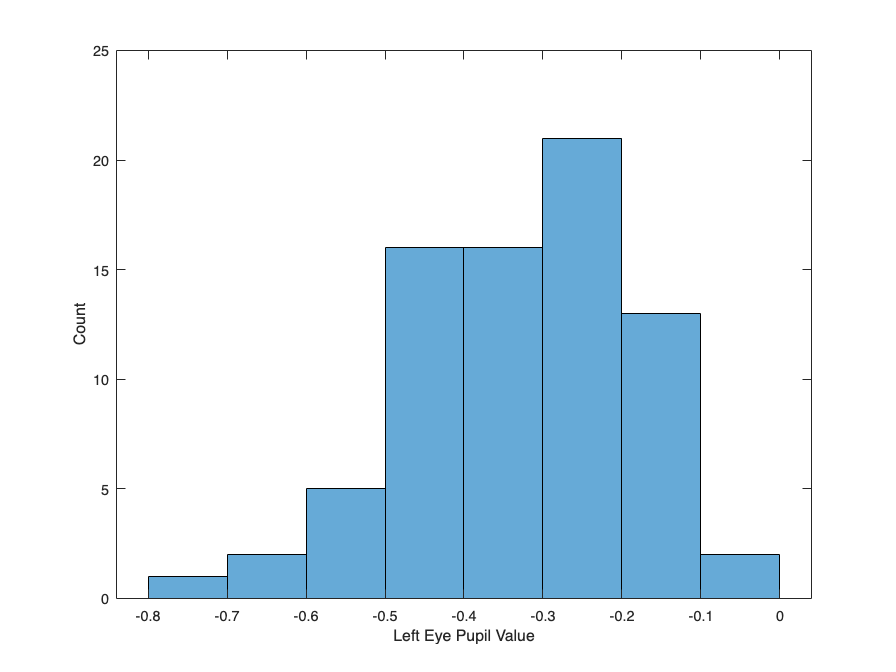


tempData3to6 = raw_eye_data{:,2:2:end};
metricLabel = "Left Eye Pupil Value";

figure; histogram(tempData3to6); xlabel(metricLabel);ylabel("Count");

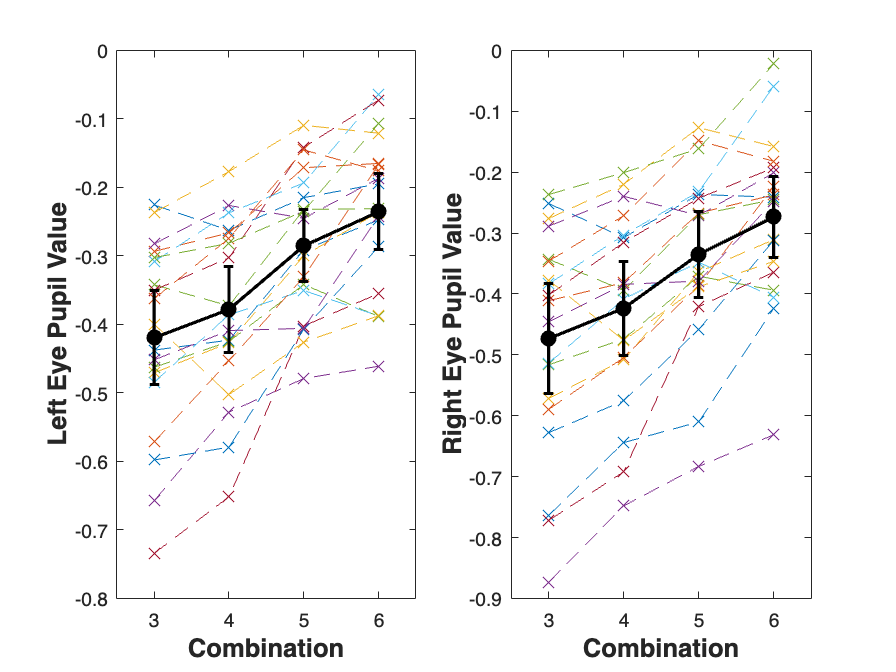

% store the data in a temporary variable to make code easy to copy, assumes
% rows are subjects and the columns are the values for 3-6 respectively

figure;
subplot(1,2,1)

for i = 1:size(tempData3to6,1)
    plot(conditionValues,tempData3to6(i,:),'x--','MarkerSize',10);
    hold on;  
end
errorVals = calculateError(tempData3to6,'95sem');
errorbar(conditionValues,mean(tempData3to6),errorVals,'k','LineWidth',2);
hold on;
plot(conditionValues,mean(tempData3to6),'k.','MarkerSize',30);
fontsize(gca,12,'points')
xlim([2.5 6.5]); xlabel('Combination','FontSize',16,"FontWeight","bold");
ylabel(metricLabel,'FontSize',16,"FontWeight","bold");
tempData3to6 = raw_eye_data{:,3:2:end};
metricLabel = "Right Eye Pupil Value";
subplot(1,2,2)

for i = 1:size(tempData3to6,1)
    plot(conditionValues,tempData3to6(i,:),'x--','MarkerSize',10);
    hold on;  
end
errorVals = calculateError(tempData3to6,'95sem');
errorbar(conditionValues,mean(tempData3to6),errorVals,'k','LineWidth',2);
hold on;
plot(conditionValues,mean(tempData3to6),'k.','MarkerSize',30);
fontsize(gca,12,'points')
xlim([2.5 6.5]); xlabel('Combination','FontSize',16,"FontWeight","bold");
ylabel(metricLabel,'FontSize',16,"FontWeight","bold");

Hot damn, that's a nice looking plot. That's an incredibly clear linear relationship with pupil value that seems to be pretty consistent across subjects. It would be interesting to see how clearly this tracks within subjects at the trial level, but maybe that's a fun future analysis  / machine learning activity.

Since we have the left and right eye, we will need to modify the models slightly to include the data from both eyes.

#### Repeated Measures ANOVA

withinDesign = table([1 1 2 2 3 3 4 4]',[1 2 1 2 1 2 1 2]','VariableNames',{'Load','Eye'});
withinDesign.Load = categorical(withinDesign.Load);
withinDesign.Eye = categorical(withinDesign.Eye);
rm_eye = fitrm(raw_eye_data,'left_x3Combination-right_x6Combination ~ 1','WithinDesign',withinDesign);
rm_eye_anova = ranova(rm_eye,'WithinModel','Load*Eye')

rm_eye_anova = 8×8 table
                              SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                            _________    __    __________    ______    __________    __________    __________    __________

    (Intercept)                18.942     1        18.942    144.41     4.933e-10     4.933e-10     4.933e-10     4.933e-10
    Error                       2.361    18       0.13117                                                                  
    (Intercept):Load          0.85577     3       0.28526    45.066    1.0048e-14    4.9123e-10    6.2441e-11    2.7054e-06
    Error(Load)        

Since we see no interaction and a main effect of Load, we need to do post hoc tests (default uses Tukey-Kramer for corrections.

rm_eye_mult = multcompare(rm_eye,'Load')

rm_eye_mult = 12×7 table
    Load_1    Load_2    Difference     StdErr       pValue        Lower        Upper   
    ______    ______    __________    ________    __________    _________    __________

      1         2       -0.045461     0.012783      0.011026    -0.081589    -0.0093326
      1         3        -0.13614     0.019331    7.9345e-06     -0.19078     -0.081509
      1         4        -0.19174     0.025009    2.4938e-06     -0.26243      -0.12106
      2         1        0.045461     0.012783      0.011026    0.0093326      0.081589
      2         3       -0.090683     0.013987    2.3382e-05     -0.13021     -0.051152
      2         4        -0.14628     0.019909    4.4811e-06     -0.20255     -0.090012
      3         1         0.1361

### Compare categorical and linear models

We can check to see if the data is better fit by a model that treats load as categorical or a model that treats it as continuous data.

First, we must reshape the data so it is organized as expected for the model.

long_eye_data = stack(raw_eye_data,{raw_eye_data.Properties.VariableNames(2:2:end) raw_eye_data.Properties.VariableNames(3:2:end)},"IndexVariableName","Load","NewDataVariableName",{'Left','Right'})

long_eye_data = 76×4 table
    ID     Load      Left       Right  
    ___    ____    ________    ________

    A02     2      -0.22557    -0.25146
    A02     4      -0.26269    -0.30748
    A02     6      -0.21496    -0.23654
    A02     8      -0.19475    -0.24111
    A05     2      -0.29337    -0.41109
    A05     4      -0.26643    -0.38144
    A05     6       -0.1713    -0.26718
    A05     8      -0.16496    -0.23728
    A07     2      -0.23685    -0.27611
    A07     4      -0.17688    -0.21994
    A07     6      -0.10935    -0.12689
    A07     8      -0.12084    -0.15778
    A08     2      -0.28256    -0.28869
    A08     4      -0.22639    -0.23961
    A08     6      -0.24521    -0.27108
    A08     8      -0.18682    -0.20104


long_eye_data = stack(long_eye_data,{'Left','Right'},"IndexVariableName","Eye","NewDataVariableName","Values");
%temp_load = char(long_eye_data.Load);
%temp_load = temp_load(:,2);
long_eye_data.LoadVal = repmat([3 3 4 4 5 5 6 6]',19,1); %str2num(temp_load(:,2));%#ok
long_eye_data.Load = categorical(long_eye_data.LoadVal)

long_eye_data = 152×5 table
    ID     Load     Eye      Values     LoadVal
    ___    ____    _____    ________    _______

    A02     3      Left     -0.22557       3   
    A02     3      Right    -0.25146       3   
    A02     4      Left     -0.26269       4   
    A02     4      Right    -0.30748       4   
    A02     5      Left     -0.21496       5   
    A02     5      Right    -0.23654       5   
    A02     6      Left     -0.19475       6   
    A02     6      Right    -0.24111       6   
    A05     3      Left     -0.29337       3   
    A05     3      Right    -0.41109       3   
    A05     4      Left     -0.26643       4   
    A05     4      Right    -0.38144       4   
    A05     5      Left      -0.1713       5   
    A05     5      Right    -0.26718       5   
    A05     6      Left     -0.16

Then we build a set of models to compare.

lme_eye_cont = fitlme(long_eye_data,'Values ~ 1 + LoadVal + Eye + (1|ID)', FitMethod='ML'); %Load as a continuous variable
lme_eye_cont_err = fitlme(long_eye_data,'Values ~ 1 + LoadVal + Eye + (1 + Eye + LoadVal|ID)', FitMethod='ML'); %Load as a continuous variable and independent slopes
lme_eye_cont_interact = fitlme(long_eye_data,'Values ~ 1 + LoadVal * Eye + (1|ID)', FitMethod='ML'); %Load as a continuous variable

lme_eye_cat = fitlme(long_eye_data,'Values ~ 1 + Load + Eye + (1|ID)', FitMethod='ML'); % Load as a categorical variable
lme_eye_cat_err = fitlme(long_eye_data,'Values ~ 1 + Load + Eye + (1 + Eye + Load|ID)', FitMethod='ML'); % Load as a categorical variable
lme_eye_cat_interact = fitlme(long_eye_data,'Values ~ 1 + Load * Eye + (1 + Eye * Load|ID)', FitMethod='ML'); % Load as a categorical variable




comparecriterion = [lme_eye_cont.ModelCriterion;  lme_eye_cont_err.ModelCriterion; lme_eye_cont_interact.ModelCriterion; ...
    lme_eye_cat.ModelCriterion; lme_eye_cat_err.ModelCriterion; lme_eye_cat_interact.ModelCriterion]

comparecriterion =     Model fit statistics

    AIC        BIC        LogLikelihood    Deviance
    -319.62     -304.5    164.81           -329.62 
    -385.91    -355.67    202.96           -405.91 
    -317.82    -299.67    164.91           -329.82 
    -318.65    -297.48    166.33           -332.65 
    -425.53    -362.03    233.76           -467.53 
     -417.5    -281.43    253.75            -507.5 


compareRsquared = [lme_eye_cont.Rsquared;  lme_eye_cont_err.Rsquared; lme_eye_cont_interact.Rsquared; lme_eye_cat.Rsquared; lme_eye_cat_err.Rsquared; lme_eye_cat_interact.Rsquared]

compareRsquared = 6×1 struct array with fields:
    Ordinary
    Adjusted


We can then compare the two error models to see if it's better to add the categorical.

compare(lme_eye_cont_err,lme_eye_cat_err)

ans =     Theoretical Likelihood Ratio Test

    Model               DF    AIC        BIC        LogLik    LRStat    deltaDF    pValue    
    lme_eye_cont_err    10    -385.91    -355.67    202.96                                   
    lme_eye_cat_err     21    -425.53    -362.03    233.76    61.615    11         4.6399e-09


From this , we see the the categorical version better explains the data, so we can use the repeated measures anova.

lme_eye_cat_err

lme_eye_cat_err = Linear mixed-effects model fit by ML

Model information:
    Number of observations             152
    Fixed effects coefficients           5
    Random effects coefficients         95
    Covariance parameters               16

Formula:
    Values ~ 1 + Load + Eye + (1 + Load + Eye | ID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -425.53    -362.03    233.76           -467.53 

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF     pValue        Lower        Upper    
    {'(Intercept)'}         -0.42302    0.032208    -13.134    147    1.4741e-26     -0.48667     -0.35937
    {'Load_4'     }         0.045461    0.012442     3.6538    147    0.00035878     0.020873     0.070049
    {'Load_5'     }          0.13614    0.018816     7.2357    147    2.3722e-11      0.09896      0.17333
    {'Load_6

anova(lme_eye_cat_err)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}         172.5    1      147    1.4741e-26
    {'Load'       }        23.744    3      147    1.3735e-12
    {'Eye'        }         7.421    1      147     0.0072287


## Helper Functions

function [errorValues ] = calculateError(dataSubjsAsRows,errorType)
    numSubj = size(dataSubjsAsRows,1);    
    switch errorType
        case 'std'
            errorValues = std(dataSubjsAsRows);
        case 'sem'
            errorValues = std(dataSubjsAsRows)./sqrt(numSubj);
        case '95sem'
            CI95 = tinv([0.025 0.975], numSubj-1);
            errorValues = CI95(2).*(std(dataSubjsAsRows)./sqrt(numSubj));
        otherwise
            warning('errorType does not match any options, returning zeros')
            errorValues = zeros(1,size(dataSubjsAsRows,2));
    end  
end